# Tratamento inicial dos dados

## Zerar workspace

clear;

## Importar CSV dos dados

Os dados originais (CSV) devem ter sido tratados previamente (editar a hora para o formato YYYY-MM-DD hh:mm:ss, adicionar linha de cabeçalho, verificar numero de colunas)

node1 = readtable('logs/csv/coleta02_20170131_20170207/1/WMLOGB_edited.CSV');
node2 = readtable('logs/csv/coleta02_20170131_20170207/2/WMLOGB_edited.CSV');
node3 = readtable('logs/csv/coleta02_20170131_20170207/3/WMLOGB_edited.CSV');
node4 = readtable('logs/csv/coleta02_20170131_20170207/4/WMLOGB_edited.CSV');

## Ajustando dados do sensor 03 do nó 4

Multiplicando por -1 para tornar os valores positivos

*FIXME: decidir se essa multiplicação será feita ou não*

% node4.sensor03value = node4.sensor03value * -1;

## Converter tabelas em timetables

node1 = table2timetable(node1);
node2 = table2timetable(node2);
node3 = table2timetable(node3);
node4 = table2timetable(node4);

## Conversão dos dados dos sensores de Ohm para cbar/kPa

utilizando a formula que leva em consideração a temperatura do solo

*Detalhe: a temperatura utilizada não é do solo, mas do sensor RTC*

% wmlog_node1.sensor01cbar = (3.213*(wmlog_node1.sensor01value./1000)+4.093)./(1-0.009733*(wmlog_node1.sensor01value./1000)-0.01205*wmlog_node1.temperature)
% wmlog_node1.sensor02cbar = (3.213*(wmlog_node1.sensor02value./1000)+4.093)./(1-0.009733*(wmlog_node1.sensor02value./1000)-0.01205*wmlog_node1.temperature)
% wmlog_node1.sensor03cbar = (3.213*(wmlog_node1.sensor03value./1000)+4.093)./(1-0.009733*(wmlog_node1.sensor03value./1000)-0.01205*wmlog_node1.temperature)

Conversão dos dados dos sensores de Ohm para cbar/kPa (utilizanda a fórmula básica de conversão da irrometer)

node1{:,3:end} = (node1{:,3:end}-550)./137.5;
node2{:,3:end} = (node2{:,3:end}-550)./137.5;
node3{:,3:end} = (node3{:,3:end}-550)./137.5;
node4{:,3:end} = (node4{:,3:end}-550)./137.5;

## Determinar período de tempo a ser utilizado e filtrar tabelas

%range = timerange('2017-01-31', '2017-02-07');
%node1 = node1(range,:);
%node2 = node2(range,:);
%node4 = node4(range,:);

**FIXME**: ajustes de escala (sensor de 15cm dos nós 1 e 2 estão em uma ordem de grandeza maior, não sei o motivo)

% node1.sensor01cbar = node1.sensor01cbar/100;
% node2.sensor01cbar = node2.sensor01cbar/100;
node1{:,3:26} = node1{:,3:26}/100;
node2{:,3:26} = node2{:,3:26}/100;

## **Ajuste da calibração dos dados**

**FIXME: verificar ****se a redução a seguir é mesmo necessária**

Segundo a documentação dos sensores watermark irrometer, eles foram calibrados para funcionar a 70ºF. A cada grau F acima de 70 é necessário reduzir a leitura em 1%

Considerando o solo a 32ºC (89.6ºF)

soil_temp = 89.6;
sensor_adjustment = (100 - (soil_temp - 70))/100;

node1{:,3:end} = node1{:,3:end} * sensor_adjustment;
node2{:,3:end} = node2{:,3:end} * sensor_adjustment;
node3{:,3:end} = node3{:,3:end} * sensor_adjustment;
node4{:,3:end} = node4{:,3:end} * sensor_adjustment;

## Equilibrando dados dos nós

Removendo dados além de 2017-01-05 10:00 (último momento com dados dos 4 nós) e a primeira medição dos nós 1, 2 e 3

node1(122:end,:) = [];
node2(122:end,:) = [];
node3(122:end,:) = [];
node4(122:end,:) = [];

node1(1,:) = [];
node2(1,:) = [];
node3(1,:) = [];
node4(1,:) = [];

## Cálculo: Nova média

Calculando novas médias para todos os nós e sensores

node1.sensor01mean = mean(node1{1:end,5:26},2,'omitnan');
node1.sensor02mean = mean(node1{1:end,29:50},2,'omitnan');
node1.sensor03mean = mean(node1{1:end,53:74},2,'omitnan');

node2.sensor01mean = mean(node2{1:end,5:26},2,'omitnan');
node2.sensor02mean = mean(node2{1:end,29:50},2,'omitnan');
node2.sensor03mean = mean(node2{1:end,53:74},2,'omitnan');

node3.sensor01mean = mean(node3{1:end,5:26},2,'omitnan');
node3.sensor02mean = mean(node3{1:end,29:50},2,'omitnan');
node3.sensor03mean = mean(node3{1:end,53:74},2,'omitnan');

node4.sensor01mean = mean(node4{1:end,5:26},2,'omitnan');
node4.sensor02mean = mean(node4{1:end,29:50},2,'omitnan');
node4.sensor03mean = mean(node4{1:end,53:74},2,'omitnan');

## Unificando dados dos sensores dos nós

% sensor1mean = [node1.sensor01value node2.sensor01value node3.sensor01value node4.sensor01value];
% sensor2mean = [node1.sensor02value node2.sensor02value node3.sensor02value node4.sensor02value];
% sensor3mean = [node1.sensor03value node2.sensor03value node3.sensor03value node4.sensor03value];

sensor1mean = [node1.sensor01mean node2.sensor01mean node3.sensor01mean node4.sensor01mean];
sensor2mean = [node1.sensor02mean node2.sensor02mean node3.sensor02mean node4.sensor02mean];
sensor3mean = [node1.sensor03mean node2.sensor03mean node3.sensor03mean node4.sensor03mean];

## Configuração de plotagem dos gráficos

Determinar variáveis para plotar linhas de indicação de umidade do solo

% DateStrings = {'2017-01-31';'2017-02-05'};
% t = datetime(DateStrings,'InputFormat','yyyy-MM-dd');
dateRange = node1.time;
dateRange(122:end,:) = [];
dateRangeString = cellstr(dateRange);

Informação de saturação do solo:

- 0 a 10: solo saturado

- 10 a 30: solo adequadamente umido (exceto areia fina)

- 30 a 60: necessita rega

- 60 a 100: necessita rega (barro pesado)

- 100 a 200: perigosamente seco

## Cálculo: Mediana

Calculando medianas para todos os nós e sensores

node1.sensor01median = median(node1{1:end,5:26},2,'omitnan');
node1.sensor02median = median(node1{1:end,29:50},2,'omitnan');
node1.sensor03median = median(node1{1:end,53:74},2,'omitnan');

node2.sensor01median = median(node2{1:end,5:26},2,'omitnan');
node2.sensor02median = median(node2{1:end,29:50},2,'omitnan');
node2.sensor03median = median(node2{1:end,53:74},2,'omitnan');

node3.sensor01median = median(node3{1:end,5:26},2,'omitnan');
node3.sensor02median = median(node3{1:end,29:50},2,'omitnan');
node3.sensor03median = median(node3{1:end,53:74},2,'omitnan');

node4.sensor01median = median(node4{1:end,5:26},2,'omitnan');
node4.sensor02median = median(node4{1:end,29:50},2,'omitnan');
node4.sensor03median = median(node4{1:end,53:74},2,'omitnan');

# Fusão

## Gráfico: Média original

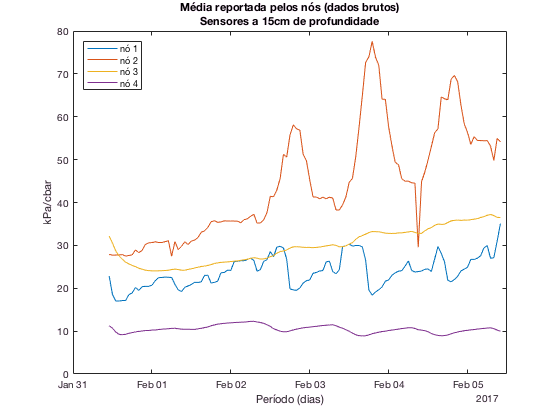

plotar_sensores(dateRange,node1.sensor01value,node2.sensor01value,node3.sensor01value,node4.sensor01value,...
    '15cm','media_original','Média reportada pelos nós (dados brutos)','northwest');

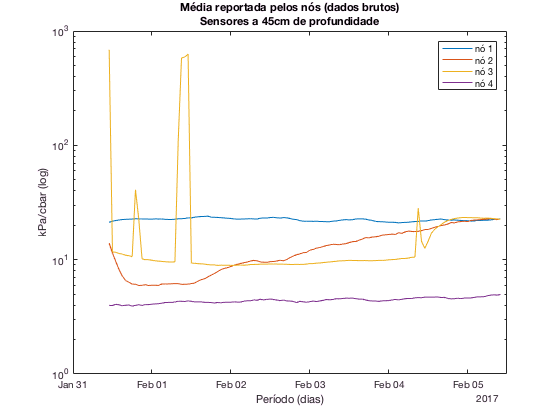

plotar_sensores(dateRange,node1.sensor02value,node2.sensor02value,node3.sensor02value,node4.sensor02value,...
    '45cm','media_original','Média reportada pelos nós (dados brutos)','northeast',true);

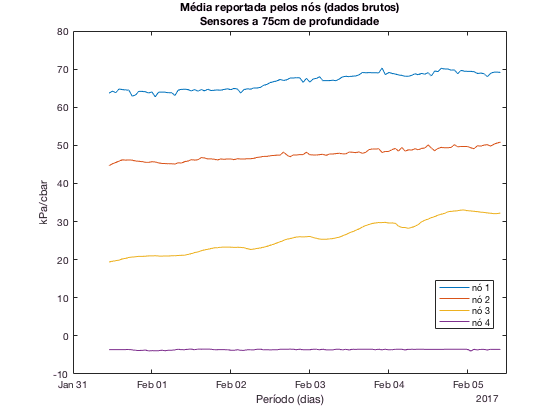

plotar_sensores(dateRange,node1.sensor03value,node2.sensor03value,node3.sensor03value,node4.sensor03value,...
    '75cm','media_original','Média reportada pelos nós (dados brutos)',[0.78 0.25 0.10 0.05]);

## Média nova

Média normal dos dados dos sensores

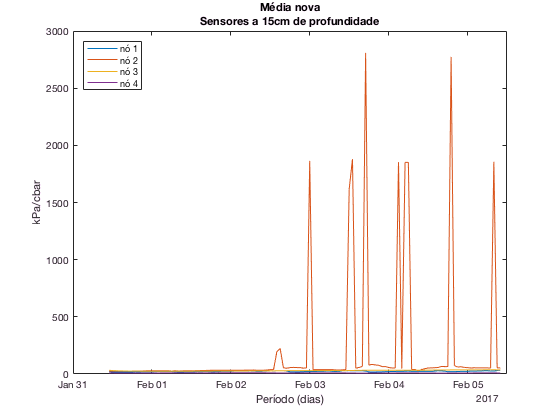

sensor1fusedMean = basicFusion(sensor1mean,'mean');
sensor2fusedMean = basicFusion(sensor2mean,'mean');
sensor3fusedMean = basicFusion(sensor3mean,'mean');

plotar_sensores(dateRange,node1.sensor01mean,node2.sensor01mean,node3.sensor01mean,node4.sensor01mean,...
    '15cm','media_nova','Média nova','northwest');

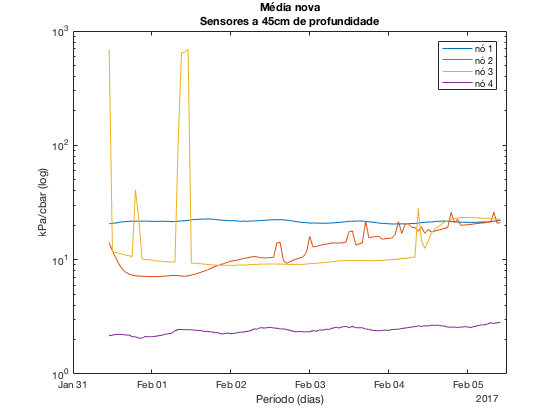

plotar_sensores(dateRange,node1.sensor02mean,node2.sensor02mean,node3.sensor02mean,node4.sensor02mean,...
    '45cm','media_nova','Média nova','northeast',true);

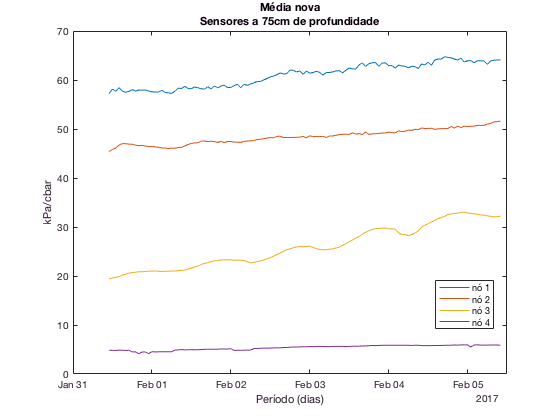

plotar_sensores(dateRange,node1.sensor03mean,node2.sensor03mean,node3.sensor03mean,node4.sensor03mean,...
    '75cm','media_nova','Média nova',[0.78 0.25 0.10 0.05]);

## Mediana

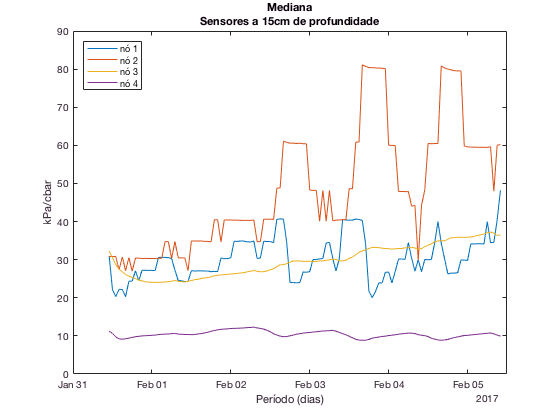

sensor1fusedMedian = basicFusion(sensor1mean,'median');
sensor2fusedMedian = basicFusion(sensor2mean,'median');
sensor3fusedMedian = basicFusion(sensor3mean,'median');

plotar_sensores(dateRange,node1.sensor01median,node2.sensor01median,node3.sensor01median,node4.sensor01median,...
    '15cm','mediana','Mediana','northwest');

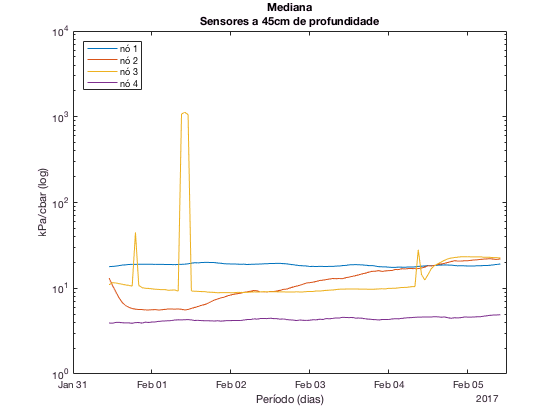

plotar_sensores(dateRange,node1.sensor02median,node2.sensor02median,node3.sensor02median,node4.sensor02median,...
    '45cm','mediana','Mediana','northwest',true);

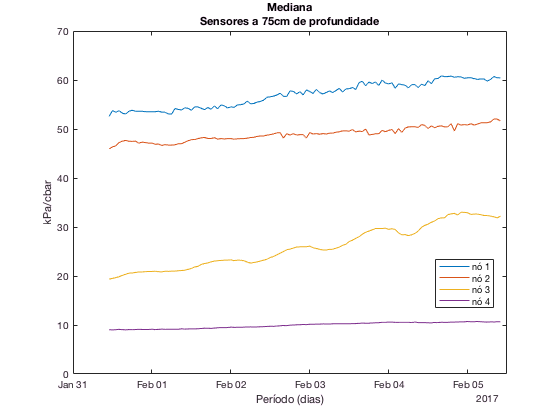

plotar_sensores(dateRange,node1.sensor03median,node2.sensor03median,node3.sensor03median,node4.sensor03median,...
    '75cm','mediana','Mediana',[0.78 0.3 0.10 0.05]);

## Peirce

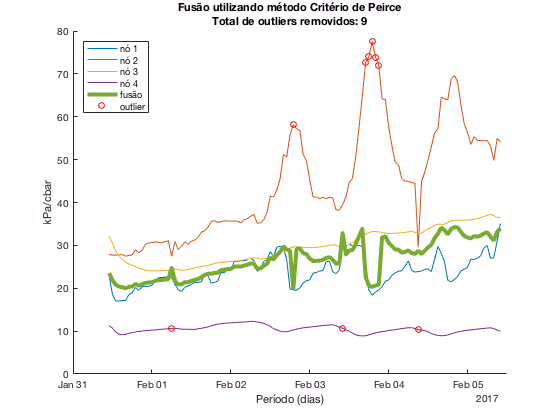

[sensor1fusedPeirce, sensor1peirceOutliers, sensor1peirceOutliersTotal] = peirceFusion(sensor1mean);
[sensor2fusedPeirce, sensor2peirceOutliers, sensor2peirceOutliersTotal] = peirceFusion(sensor2mean);
[sensor3fusedPeirce, sensor3peirceOutliers, sensor3peirceOutliersTotal] = peirceFusion(sensor3mean);

plotar_metodo_alt(dateRange,sensor1mean,sensor1fusedPeirce,...
    '15cm_fusao_peirce','Critério de Peirce',sensor1peirceOutliersTotal,'northwest',sensor1peirceOutliers);

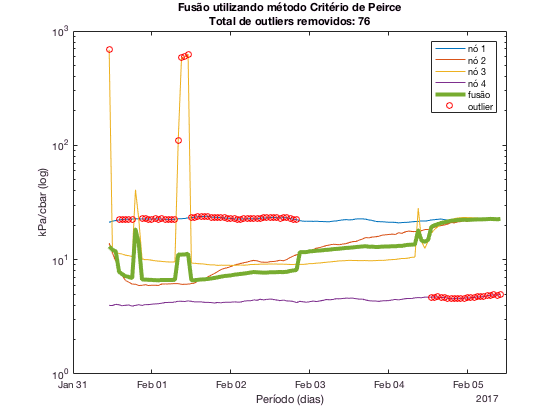

plotar_metodo_alt_log(dateRange,sensor2mean,sensor2fusedPeirce,...
    '45cm_fusao_peirce','Critério de Peirce',sensor2peirceOutliersTotal,'northeast',sensor2peirceOutliers);

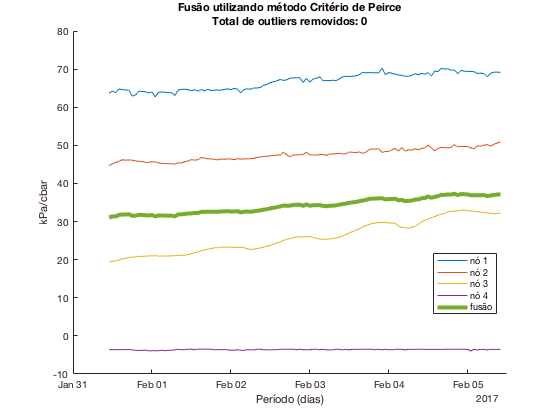

plotar_metodo_alt(dateRange,sensor3mean,sensor3fusedPeirce,...
    '75cm_fusao_peirce','Critério de Peirce',sensor3peirceOutliersTotal,[0.78 0.3 0.10 0.05],sensor3peirceOutliers);

## Chauvenet

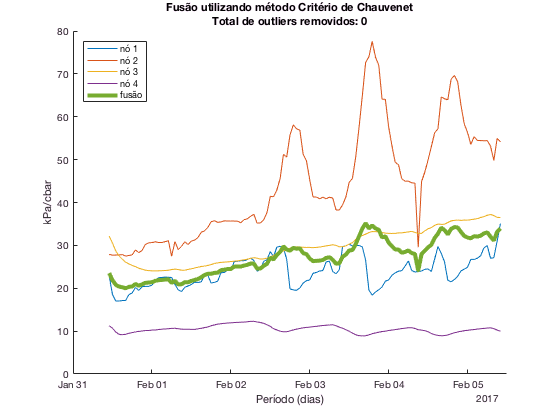

[sensor1fusedChauvenet, sensor1chauvenetOutliers, sensor1chauvenetOutliersTotal] = chauvenetFusion(sensor1mean);
[sensor2fusedChauvenet, sensor2chauvenetOutliers, sensor2chauvenetOutliersTotal] = chauvenetFusion(sensor2mean);
[sensor3fusedChauvenet, sensor3chauvenetOutliers, sensor3chauvenetOutliersTotal] = chauvenetFusion(sensor3mean);

plotar_metodo(dateRange,sensor1mean,sensor1fusedChauvenet,...
    '15cm_fusao_chauvenet','Critério de Chauvenet',sensor1chauvenetOutliersTotal,'northwest',sensor1chauvenetOutliers);

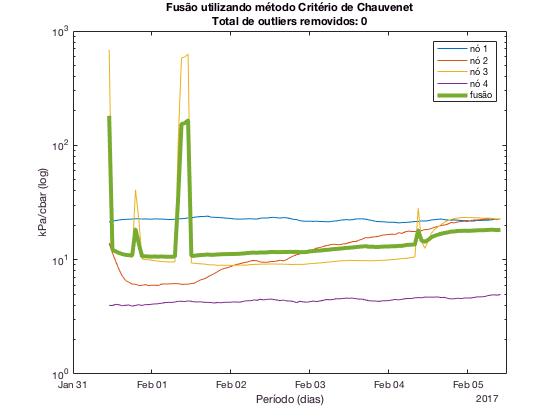

plotar_metodo_log(dateRange,sensor2mean,sensor2fusedChauvenet,...
    '45cm_fusao_chauvenet','Critério de Chauvenet',sensor2chauvenetOutliersTotal,'northeast',sensor2chauvenetOutliers);

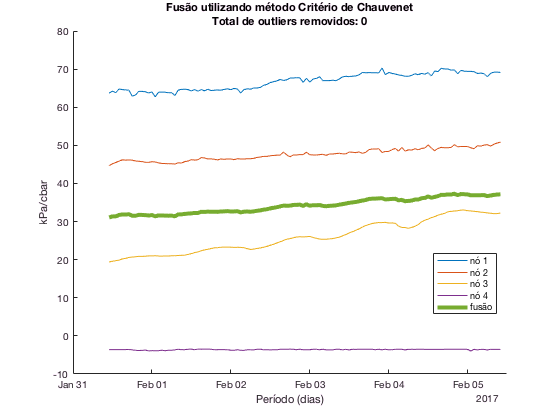

plotar_metodo(dateRange,sensor3mean,sensor3fusedChauvenet,...
    '75cm_fusao_chauvenet','Critério de Chauvenet',sensor3chauvenetOutliersTotal,[0.78 0.3 0.10 0.05],sensor3chauvenetOutliers);

## Z-score

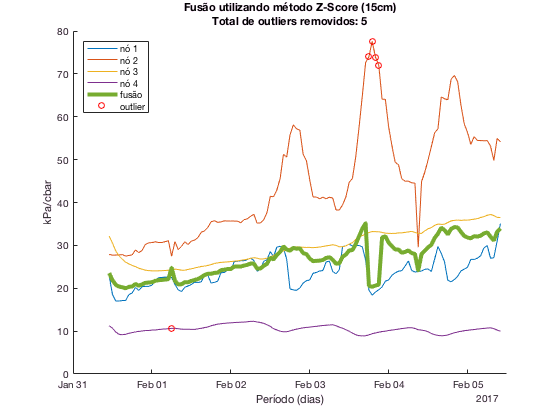

% threshold padrão de 3.0 alterado para 1.4, do contrário nenhum outlier teria sido detectado, nem mesmo os mais extremos. Ex.: sensor1meanT(62,:)
[sensor1fusedZScore, sensor1zScoreOutliersIndex, sensor1zScoreOutliersTotal, sensor1zScores] = zScoreFusion(sensor1mean,dateRangeString,1.4);
[sensor2fusedZScore, sensor2zScoreOutliersIndex, sensor2zScoreOutliersTotal, sensor2zScores] = zScoreFusion(sensor2mean,dateRangeString,1.4);
[sensor3fusedZScore, sensor3zScoreOutliersIndex, sensor3zScoreOutliersTotal, sensor3zScores] = zScoreFusion(sensor3mean,dateRangeString,1.4);

plotar_metodo(dateRange,sensor1mean,sensor1fusedZScore,...
    '15cm_fusao_zScore','Z-Score (15cm)',sensor1zScoreOutliersTotal,'northwest',sensor1zScoreOutliersIndex);

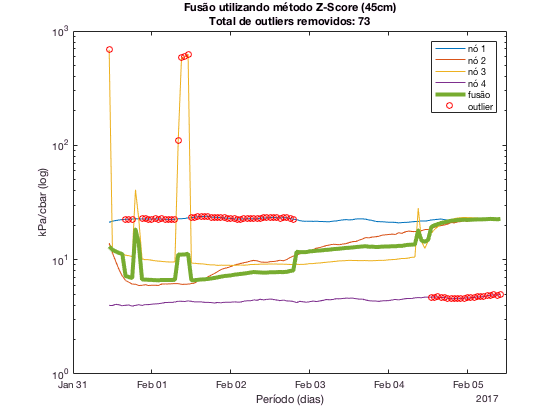

plotar_metodo_log(dateRange,sensor2mean,sensor2fusedZScore,...
    '45cm_fusao_zScore','Z-Score (45cm)',sensor2zScoreOutliersTotal,'northeast',sensor2zScoreOutliersIndex);

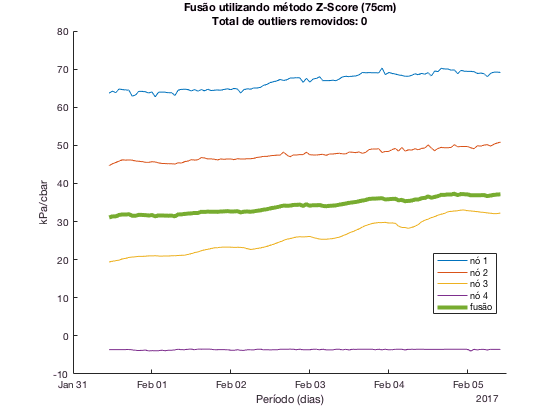

plotar_metodo(dateRange,sensor3mean,sensor3fusedZScore,...
    '75cm_fusao_zScore','Z-Score (75cm)',sensor3zScoreOutliersTotal,[0.78 0.3 0.10 0.05],sensor3zScoreOutliersIndex);

## Modified Z-score

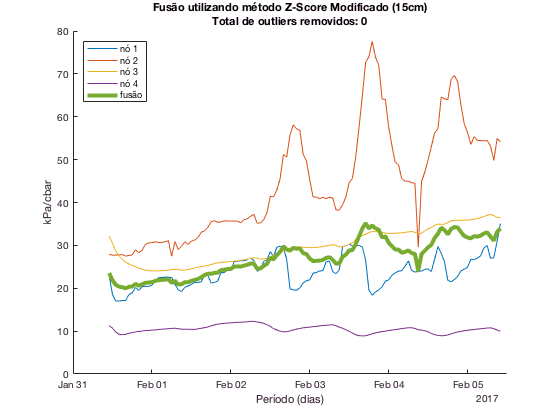

% threshold padrão de 3.5 foi mantido
[sensor1fusedMZScore, sensor1mzScoreOutliersIndex, sensor1mzScoreOutliersTotal, sensor1mzScores] = mzScoreFusion(sensor1mean,dateRangeString,3.5);
[sensor2fusedMZScore, sensor2mzScoreOutliersIndex, sensor2mzScoreOutliersTotal, sensor2mzScores] = mzScoreFusion(sensor2mean,dateRangeString,3.5);
[sensor3fusedMZScore, sensor3mzScoreOutliersIndex, sensor3mzScoreOutliersTotal, sensor3mzScores] = mzScoreFusion(sensor3mean,dateRangeString,3.5);

plotar_metodo(dateRange,sensor1mean,sensor1fusedMZScore,...
    '15cm_fusao_ZScoreModif','Z-Score Modificado (15cm)',sensor1mzScoreOutliersTotal,'northwest',sensor1mzScoreOutliersIndex);

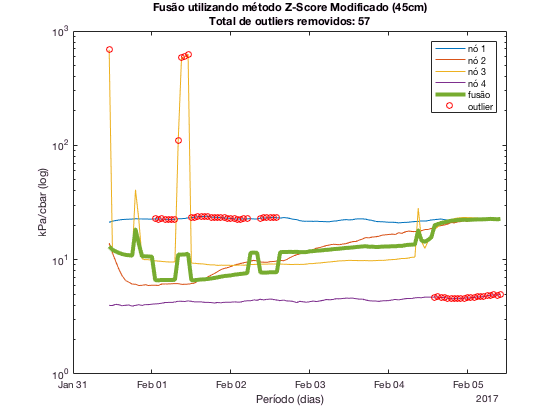

plotar_metodo_log(dateRange,sensor2mean,sensor2fusedMZScore,...
    '45cm_fusao_ZScoreModif','Z-Score Modificado (45cm)',sensor2mzScoreOutliersTotal,'northeast',sensor2mzScoreOutliersIndex);

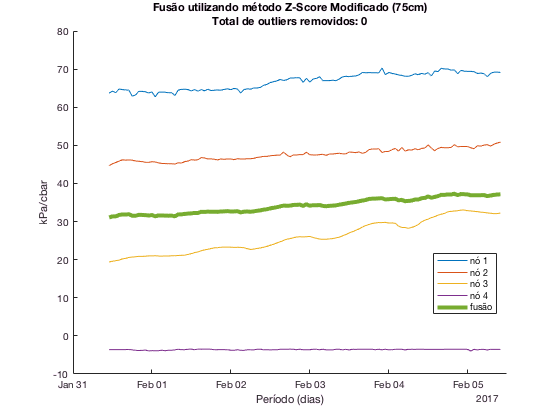

plotar_metodo(dateRange,sensor3mean,sensor3fusedMZScore,...
    '75cm_fusao_ZScoreModif','Z-Score Modificado (75cm)',sensor3mzScoreOutliersTotal,[0.78 0.3 0.10 0.05],sensor3mzScoreOutliersIndex);

## Filtro de Kalman

## Parâmetros

Covariância do ruídos das medições *#FIXME: falta atualizar esses valores. Utilizando os valores do exemplo.*

% for our single-sensor example, we defined 'r' as the variance of the observation
% noise signal 'vk'; that is, how much it varies around its mean (average) value.
% For a system with more than two sensors, 'R' is a matrix containing the 
% covariance between each pair of sensors

% Let's say that we've observed both our thermometers under climate-controlled
% conditions of steady temperature, and observed that their values fluctuate by
% an average of 0.8 degrees; i.e., the standard deviation of their readings is
% 0.8, making the variance 0.8 * 0.8 = 0.64
% R = [R1 0 0 0
%      0 R2 0 0
%      0 0 R3 0
%      0 0 0 R4]
R1 = 0.64;
R2 = 0.64;
R3 = 0.64;
R4 = 0.64;

Covariância do ruído do processo *#FIXME: falta** atualizar esse valor. Utilizando o valor do exemplo.*

Q = .005;

Estado do modelo de transição. Como o estado anterior não é conhecido então se inicia em 1

% we'll assume we have no knowledge of the state-transition model
% ('A' matrix) and so have to rely only on the sensor values
A = 1;

Modelo de observação (qual o grau de influencia dos dados do sensores na estimativa dos dados. Max: 1)

% We'll assume that both sensors contribute equally to our temperature estimation,
% so our CC matrix is just a pair of 1's
C1 = 1;
C2 = 1;
C3 = 1;
C4 = 1;

% gerando transpostas para facilitar o uso do filtro
sensor1meanT = sensor1mean';
sensor2meanT = sensor2mean';
sensor3meanT = sensor3mean';

% 1 sensor
sensor1fusedKAF1 = kalman([sensor1meanT(1,:)], A, [C1], [R1], Q);

% 2 sensores
sensor1fusedKAF2 = kalman([sensor1meanT(1,:); sensor1meanT(2,:)], A, [C1; C2], [R1 0; 0 R2], Q);

% 3 sensores
sensor1fusedKAF3 = kalman([sensor1meanT(1,:); sensor1meanT(2,:); sensor1meanT(3,:)], A, [C1; C2; C3], [R1 0 0; 0 R2 0; 0 0 R3], Q);

% 4 sensores
sensor1fusedKAF4 = kalman([sensor1meanT(1,:); sensor1meanT(2,:); sensor1meanT(3,:); sensor1meanT(4,:)], A, [C1; C2; C3; C4], [R1 0 0 0; 0 R2 0 0; 0 0 R3 0; 0 0 0 R4], Q);
sensor2fusedKAF4 = kalman([sensor2meanT(1,:); sensor2meanT(2,:); sensor2meanT(3,:); sensor2meanT(4,:)], A, [C1; C2; C3; C4], [R1 0 0 0; 0 R2 0 0; 0 0 R3 0; 0 0 0 R4], Q);
sensor3fusedKAF4 = kalman([sensor3meanT(1,:); sensor3meanT(2,:); sensor3meanT(3,:); sensor3meanT(4,:)], A, [C1; C2; C3; C4], [R1 0 0 0; 0 R2 0 0; 0 0 R3 0; 0 0 0 R4], Q);

# Gráficos

## Comparação Kalman

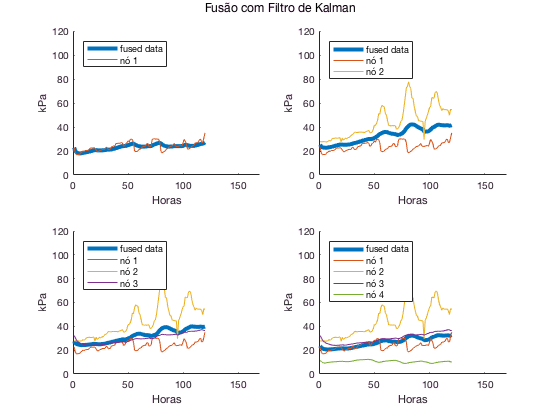

clf % clear current figure
kalmanSubplot = figure;
a = subplot(2,2,1);
hold on
plot(sensor1fusedKAF1,'DisplayName','fused data','LineWidth',4)
plot(node1.sensor01value,'DisplayName','nó 1')
legend('show','Location','northwest')
ylabel('kPa')
xlabel('Horas')
xlim([0 170])
ylim([0 120])
% title(a,'1 nó')
hold off

b = subplot(2,2,2);
hold on
plot(sensor1fusedKAF2,'DisplayName','fused data','LineWidth',4)
plot(node1.sensor01value,'DisplayName','nó 1')
plot(node2.sensor01value,'DisplayName','nó 2')
legend('show','Location','northwest')
ylabel('kPa')
xlabel('Horas')
xlim([0 170])
ylim([0 120])
hold off

c = subplot(2,2,3);
hold on
plot(sensor1fusedKAF3,'DisplayName','fused data','LineWidth',4)
plot(node1.sensor01value,'DisplayName','nó 1')
plot(node2.sensor01value,'DisplayName','nó 2')
plot(node3.sensor01value,'DisplayName','nó 3')
legend('show','Location','northwest')
ylabel('kPa')
xlabel('Horas')
xlim([0 170])
ylim([0 120])
hold off

d = subplot(2,2,4);
hold on
plot(sensor1fusedKAF4,'DisplayName','fused data','LineWidth',4)
plot(node1.sensor01value,'DisplayName','nó 1')
plot(node2.sensor01value,'DisplayName','nó 2')
plot(node3.sensor01value,'DisplayName','nó 3')
plot(node4.sensor01value,'DisplayName','nó 4')
legend('show','Location','northwest')
ylabel('kPa')
xlabel('Horas')
xlim([0 170])
ylim([0 120])
hold off

figtitle('Fusão com Filtro de Kalman');
saveas(kalmanSubplot,'graphs/sensores_15cm_kalman','png');

# Gráfico comparativo de fusão

Plotar gráfico comparativo

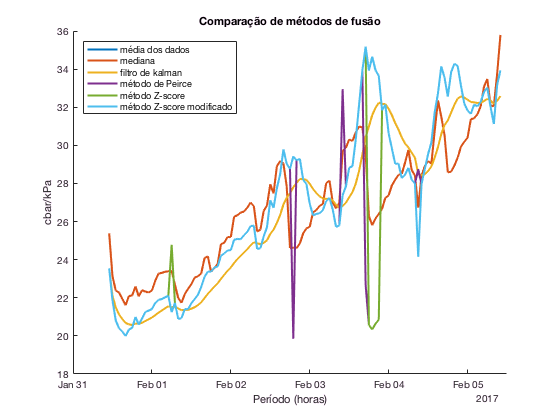

clf
fusionCompare = figure;
hold on
semilogy(dateRange,sensor1fusedMean,'DisplayName','média dos dados','LineWidth',2);
% semilogy(sensor1fusedMAF6,'DisplayName','média móvel (6)','LineWidth',2);
% semilogy(sensor1fusedMAF12,'DisplayName','média móvel (12)','LineWidth',2);
semilogy(dateRange,sensor1fusedMedian,'DisplayName','mediana','LineWidth',2);
semilogy(dateRange,sensor1fusedKAF4,'DisplayName','filtro de kalman','LineWidth',2);
semilogy(dateRange,sensor1fusedPeirce,'DisplayName','método de Peirce','LineWidth',2);
semilogy(dateRange,sensor1fusedZScore,'DisplayName','método Z-score','LineWidth',2);
semilogy(dateRange,sensor1fusedMZScore,'DisplayName','método Z-score modificado','LineWidth',2);
% plot([0 180],[10 10], 'k--','HandleVisibility','off'); % 0 a 10: solo saturado
% saturado = text(180,5,'saturado','HorizontalAlignment','center');
% set(saturado,'rotation',90);
% umido = text(180,20,'úmido','HorizontalAlignment','center');
% set(umido,'rotation',90);
% plot([0 180],[30 30], 'k--','HandleVisibility','off'); % 10 a 30: solo adequadamente umido (exceto areia fina)
% irrigar1 = text(180,45,'irrigar','HorizontalAlignment','center');
% set(irrigar1,'rotation',90);
% plot([0 180],[60 60], 'k--','HandleVisibility','off'); % 30 a 60: necessita rega
% irrigar2 = text(180,80,'irrigar','HorizontalAlignment','center');
% set(irrigar2,'rotation',90);
% plot([0 180],[100 100], 'k--','HandleVisibility','off'); % 60 a 100: necessita rega (barro pesado)
% seco = text(180,150,'seco','HorizontalAlignment','center');
% set(seco,'rotation',90);
% plot([0 180],[200 200], 'k--','HandleVisibility','off'); % 100 a 200: perigosamente seco
hold off
legend('Location','northwest')
ylabel('cbar/kPa')
xlabel('Período (horas)')


title('Comparação de métodos de fusão');
saveas(fusionCompare,'graphs/sensores_comparacao_fusao_15cm','jpg')

Plotar gráfico comparativo

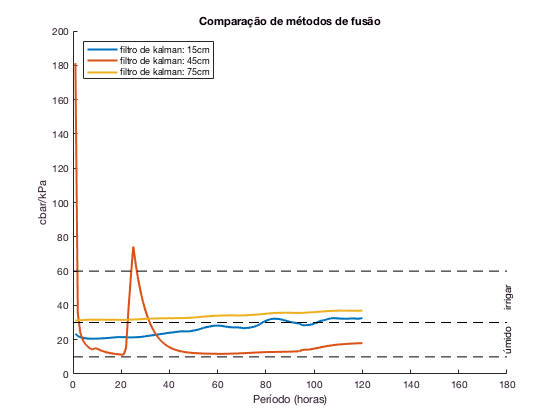

clf
fusionCompare = figure;
hold on
plot(sensor1fusedKAF4,'DisplayName','filtro de kalman: 15cm','LineWidth',2);
plot(sensor2fusedKAF4,'DisplayName','filtro de kalman: 45cm','LineWidth',2);
plot(sensor3fusedKAF4,'DisplayName','filtro de kalman: 75cm','LineWidth',2);
plot([0 180],[10 10], 'k--','HandleVisibility','off'); % 0 a 10: solo saturado
% saturado = text(180,5,'saturado','HorizontalAlignment','center');
% set(saturado,'rotation',90);
umido = text(180,20,'úmido','HorizontalAlignment','center');
set(umido,'rotation',90);
plot([0 180],[30 30], 'k--','HandleVisibility','off'); % 10 a 30: solo adequadamente umido (exceto areia fina)
irrigar1 = text(180,45,'irrigar','HorizontalAlignment','center');
set(irrigar1,'rotation',90);
plot([0 180],[60 60], 'k--','HandleVisibility','off'); % 30 a 60: necessita rega
% irrigar2 = text(180,80,'irrigar','HorizontalAlignment','center');
% set(irrigar2,'rotation',90);
% plot([100 100], 'k--','HandleVisibility','off'); % 60 a 100: necessita rega (barro pesado)
% seco = text(8,150,'perigosamente seco','HorizontalAlignment','center');
% set(seco,'rotation',90);
% plot([200 200], 'k--','HandleVisibility','off'); % 100 a 200: perigosamente seco
hold off
legend('Location','northwest')
ylabel('cbar/kPa')
xlabel('Período (horas)')
hold off

title('Comparação de métodos de fusão');
saveas(fusionCompare,'graphs/sensores_todos_fusao_kalman','jpg')

Testes

function plotar_sensores(period,sensor1,sensor2,sensor3,sensor4,depth,type,plotTitle,legendPosition,plotYlog)
    if nargin < 10
        plotYlog = false;
    end
    grafico = figure;
    ylim([-5; Inf]);
    if plotYlog == false
        plot(period,[sensor1, sensor2, sensor3, sensor4])
        hold on
    else
        semilogy(period,[sensor1, sensor2, sensor3, sensor4])
        hold on
    end
%     DateStrings = {'2017-01-31 11:00';'2017-02-05 10:00'};
%     t = datetime(DateStrings,'InputFormat','yyyy-MM-dd hh:mm');
%     saturado = text(8,5,'saturado','HorizontalAlignment','center');
    % set(saturado,'rotation',90);
%     plot(t,[10 10], 'k--','HandleVisibility','off'); % 0 a 10: solo saturado
%     umido = text(8,20,'úmido','HorizontalAlignment','center');
%     set(umido,'rotation',90);
%     plot(t,[30 30], 'k--','HandleVisibility','off'); % 10 a 30: solo adequadamente umido (exceto areia fina)
%     irrigar1 = text(8,45,'irrigar','HorizontalAlignment','center');
%     set(irrigar1,'rotation',90);
%     plot(t,[60 60], 'k--','HandleVisibility','off'); % 30 a 60: necessita rega
%     irrigar2 = text(8,80,'irrigar','HorizontalAlignment','center');
%     set(irrigar2,'rotation',90);
%     plot(t,[100 100], 'k--','HandleVisibility','off'); % 60 a 100: necessita rega (barro pesado)
%     seco = text(8,150,'perigosamente seco','HorizontalAlignment','center');
%     set(seco,'rotation',90);
%     plot(t,[200 200], 'k--','HandleVisibility','off'); % 100 a 200: perigosamente seco
    hold off
    legend('nó 1','nó 2','nó 3','nó 4','location',legendPosition)
    if plotYlog == false
        ylabel('kPa/cbar')
    else
        ylabel('kPa/cbar (log)')
    end
    xlabel('Período (dias)')
    titleDepth = sprintf('Sensores a %s de profundidade',depth);
    title({plotTitle,titleDepth});
    filename = sprintf('graphs/sensores_%s_%s',depth,type);
    saveas(grafico,filename,'png')
    
%     function plotsigs(pos, sig1, sig2, sig1label)
% subplot(3,1,pos)
% hold on
% plot(sig1, 'k')
% plot(sig2, 'r')
% legend({sig1label, 'Estimated'})
% ylim([15 40])
% hold off
end

function plotar_metodo(period,sensor,methodData,type,graphTitle,outlierCount,legendPosition,outlierIndex)
    if nargin < 8
        outlierIndex = NaN;
    end
    
    grafico = figure;
%     semilogy(period,sensor);
    hold on
    plot(period,sensor);
    plot(period,methodData,'LineWidth',4);
    if ~isnan(outlierIndex)
        for i = 1:size(sensor,1)
        	if (outlierIndex(i) ~= 0)
        		plot(period(i),sensor(i,outlierIndex(i)),'LineStyle','none','Marker','o','MarkerEdgeColor','red');
        	end
        end
    end
    hold off
    titleOutliers = sprintf('Total de outliers removidos: %d',outlierCount);
    methodName = sprintf('Fusão utilizando método %s',graphTitle);
    title({methodName,titleOutliers});
    xlabel('Período (dias)');
    ylabel('kPa/cbar');
    legend('nó 1','nó 2','nó 3','nó 4','fusão','outlier','location',legendPosition)
    filename = sprintf('graphs/sensores_%s',type);
    saveas(grafico,filename,'png');
end

function plotar_metodo_log(period,sensor,methodData,type,graphTitle,outlierCount,legendPosition,outlierIndex)
    if nargin < 8
        outlierIndex = NaN;
    end
    
    grafico = figure;
    semilogy(period,sensor);
    hold on
    semilogy(period,methodData,'LineWidth',4);
    if ~isnan(outlierIndex)
        for i = 1:size(sensor,1)
        	if (outlierIndex(i) ~= 0)
        		semilogy(period(i),sensor(i,outlierIndex(i)),'LineStyle','none','Marker','o','MarkerEdgeColor','red');
        	end
        end
    end
    hold off
    titleOutliers = sprintf('Total de outliers removidos: %d',outlierCount);
    methodName = sprintf('Fusão utilizando método %s',graphTitle);
    title({methodName,titleOutliers});
    xlabel('Período (dias)');
    ylabel('kPa/cbar (log)');
    legend('nó 1','nó 2','nó 3','nó 4','fusão','outlier','location',legendPosition)
    filename = sprintf('graphs/sensores_%s',type);
    saveas(grafico,filename,'png');
end

function plotar_metodo_alt(period,sensor,methodData,type,graphTitle,outlierCount,legendPosition,outlierIndex)
    grafico = figure;
    hold on
    plot(period,sensor);
    plot(period,methodData,'LineWidth',4);
    for i = 1:size(outlierIndex,1)
        plot(period(outlierIndex(i,1)),outlierIndex(i,2),'LineStyle','none','Marker','o','MarkerEdgeColor','red')
    end
    hold off
    titleOutliers = sprintf('Total de outliers removidos: %d',outlierCount);
    methodName = sprintf('Fusão utilizando método %s',graphTitle);
    title({methodName,titleOutliers});
    xlabel('Período (dias)');
    ylabel('kPa/cbar');
    legend('nó 1','nó 2','nó 3','nó 4','fusão','outlier','location',legendPosition)
    filename = sprintf('graphs/sensores_%s',type);
    saveas(grafico,filename,'png');
end

function plotar_metodo_alt_log(period,sensor,methodData,type,graphTitle,outlierCount,legendPosition,outlierIndex)
    grafico = figure;
    semilogy(period,sensor);
    hold on
    semilogy(period,methodData,'LineWidth',4);
    for i = 1:size(outlierIndex,1)
        semilogy(period(outlierIndex(i,1)),outlierIndex(i,2),'LineStyle','none','Marker','o','MarkerEdgeColor','red')
    end
    hold off
    titleOutliers = sprintf('Total de outliers removidos: %d',outlierCount);
    methodName = sprintf('Fusão utilizando método %s',graphTitle);
    title({methodName,titleOutliers});
    xlabel('Período (dias)');
    ylabel('kPa/cbar (log)');
    legend('nó 1','nó 2','nó 3','nó 4','fusão','outlier','location',legendPosition)
    filename = sprintf('graphs/sensores_%s',type);
    saveas(grafico,filename,'png');
end